# LIME

#### Fred liu 2022.5.20

**載入模型與影像(Load Model & Image)**

net = resnet50;
img = imread("t02.jpg");

**影像辨識(Image Classify)**

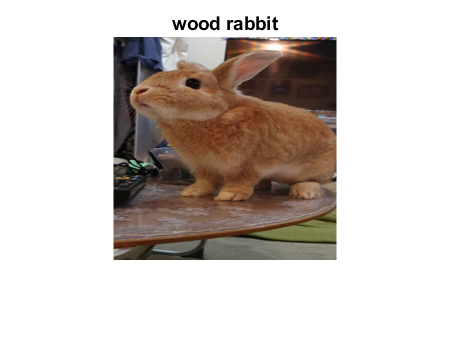

inputSize = net.Layers(1).InputSize(1:2);
classes = net.Layers(end).Classes;

re_img = imresize(img,inputSize);
figure,imshow(re_img)

[YPred,scores] = classify(net,re_img);
title(char(YPred))

**前三高類別(Top 3 Class)**

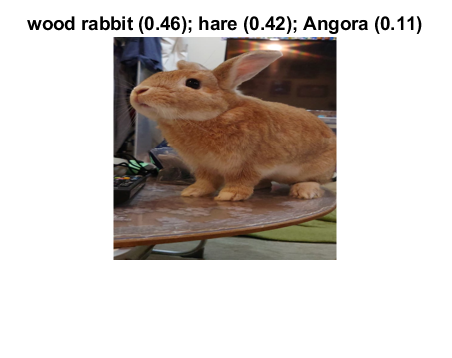

%% List top 3 class scores
[~,topIdx] = maxk(scores, 3);
topScores = scores(topIdx);
topClasses = classes(topIdx);

imshow(re_img)
titleString = compose("%s (%.2f)",topClasses,topScores');
title(sprintf(join(titleString, "; ")));

**LIME**

map = imageLIME(net,re_img,YPred);

**可視化(Visualization)**

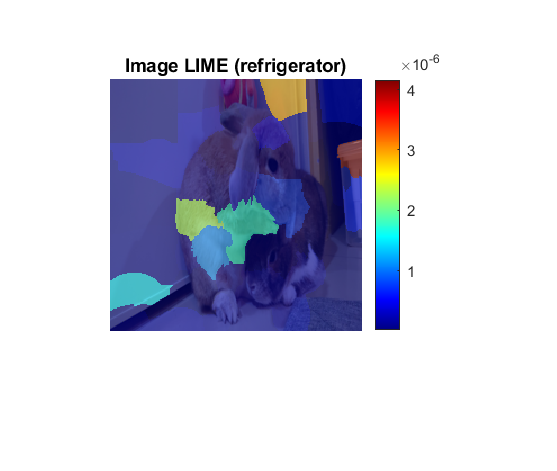

figure,imshow(re_img,'InitialMagnification',150)
hold on
imagesc(map,'AlphaData',0.5)
colormap jet
colorbar

title(sprintf("Image LIME (%s)", ...
    YPred))
hold off

**比對第二類or不同類別結果(Compare to Results of a Different Class)**

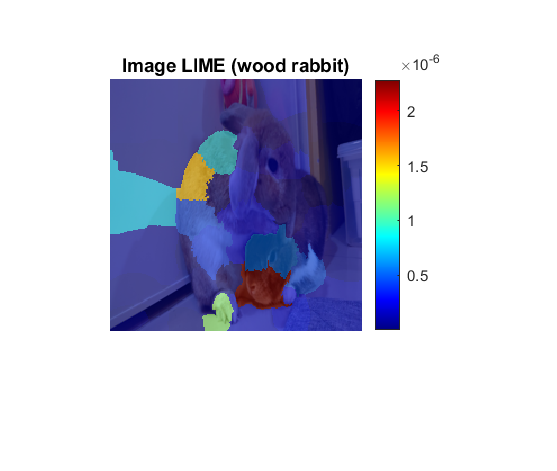

secondClass = topClasses(2);
map = imageLIME(net,re_img,secondClass);
figure,imshow(re_img,'InitialMagnification',150)
hold on
imagesc(map,'AlphaData',0.5)
colormap jet
colorbar

title(sprintf("Image LIME (%s)",secondClass))
hold off

**LIM與Grad-CAM比較(Compare LIME with Grad-CAM)**

map = imageLIME(net,re_img,"golden retriever", ...
    "Segmentation","grid",...
    "OutputUpsampling","bicubic",...
    "NumFeatures",100,...
    "NumSamples",6000,...
    "Model","linear");

Error using imageLIME
Encountered unexpected
error during CUDA
execution. The CUDA
error was:
CUDA_ERROR_LAUNCH_TIMEOUT


imshow(re_img,'InitialMagnification', 150)
hold on
imagesc(map,'AlphaData',0.5)
colormap jet

title(sprintf("Image LIME (%s - linear model)", ...
    YPred))
hold off


**重要特徵顯示(Display Only the Most Important Features)**

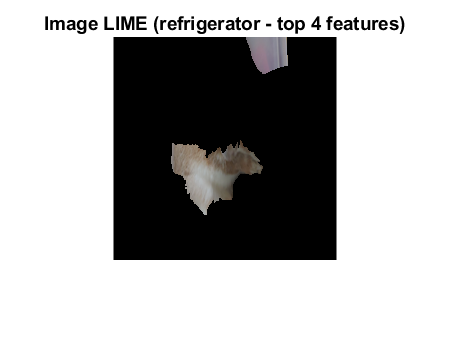

[map,featureMap,featureImportance] = imageLIME(net,re_img,YPred);

numTopFeatures = 4;
[~,idx] = maxk(featureImportance,numTopFeatures);

mask = ismember(featureMap,idx);
maskedImg = uint8(mask).*re_img;

figure
imshow(maskedImg);

title(sprintf("Image LIME (%s - top %i features)", ...
    YPred, numTopFeatures))